## 2D CWT Fitting Dev

After homography and cropping the master ROI, perform the same on the DE data files.

- Load Hom Crop file of angle scan (diffracted signal)

- Change imageset to doubles

- Re-size images

- Pick Bragglett control points - middle to start

% Load pre-processed angle scan video
clear; close all; clc;
Diff_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_06_10_01/CAM AS-2025-06-10-01-S1 Object Diffracted LowExp HOM CROP.mat";
load(Diff_directory);
DIFF = HMT_CROP_DATA; clear("HMT_CROP_DATA");

% Open up needed variables
angle_data     = DIFF.S_Beam.AS_Cam.Angle_Data;
images_cam     = DIFF.S_Beam.Crop.Cropped_Images;
bisector_angle = DIFF.S_Beam.In_Data.Bisector_Angle_AS;


#### Play CROPPED angle scan video:

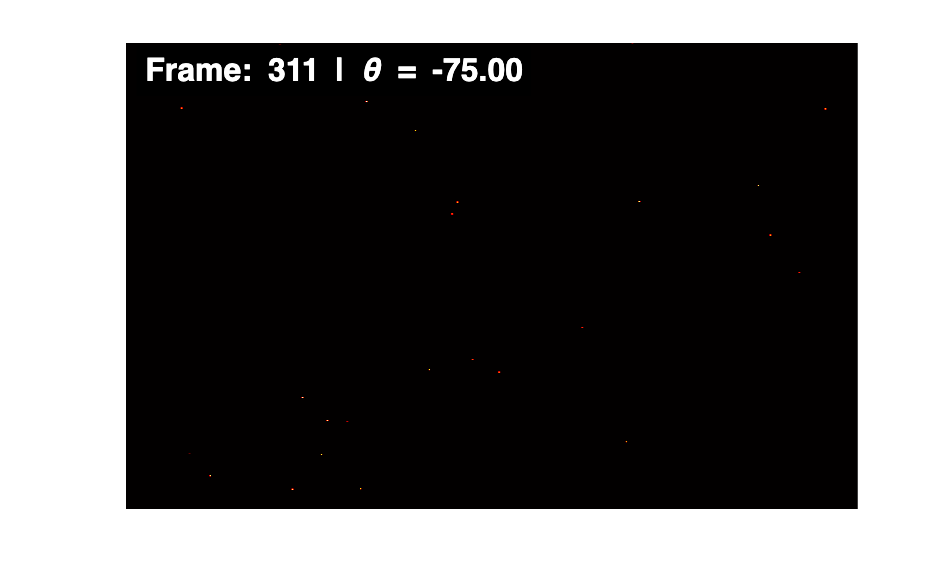

% Test the cropped ROI through the angle scan range
 
vid_image_data = images_cam;
vid_angle_data = angle_data;
fps = 30; frame_skip = 1;
playAngleScanVideoWithOptions(vid_image_data, vid_angle_data, fps, frame_skip);

clear("vid_image_data","vid_angle_data","fps","frame_skip");


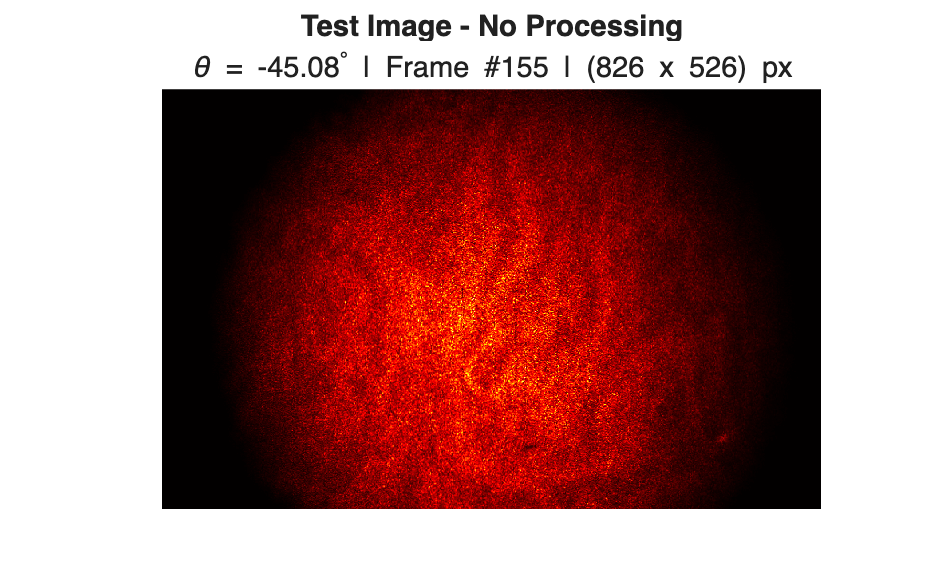

% dataset sizes
num_frames = size(images_cam,2);
[cam_height, cam_width] = size(images_cam{1,1});

% Turn imageset into 3D matrix of doubles
images = NaN(cam_height,cam_width,num_frames);

% Convert imageset from uint16 to matrix of doubles
for frame_idx = 1:num_frames
    images(:,:,frame_idx) = double(images_cam{frame_idx});
end
clear("frame_idx");

% Create test image from specified angle
test_image_angle = -45;
[test_image_angle_real, test_image_idx] = matchClosestValues(angle_data, test_image_angle, 0.5);

% Assign and plot test image 01
test_image = images(:,:,test_image_idx);

figure;
imagesc(test_image); axis image off; colormap("hot");
title("Test Image - No Processing");
subtitle(sprintf("\\theta = %.2f^{\\circ} | Frame #%i | (%i x %i) px",test_image_angle_real,test_image_idx,cam_width,cam_height));

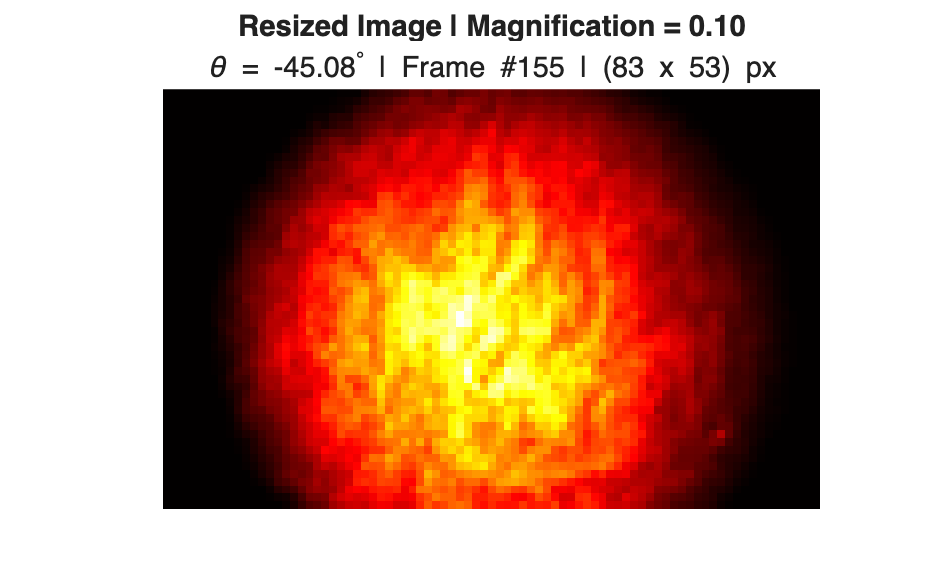


% Resize image for lower-resolution fitting
mag_factor = 0.1; % reduce the image size to reduce fitting points

% Loop through images to resize
for frame_idx = 1:num_frames
    images_resized(:,:,frame_idx) = imresize(images(:,:,frame_idx), mag_factor);
end
clear("frame_idx");

% Assign re-sized height and width
[cam_height, cam_width, ~] = size(images_resized);

% Re-assign to images variable and plot test image
images = images_resized; clear("images_resized");
test_image = images(:,:,test_image_idx);

figure;
imagesc(test_image); axis image off; colormap("hot");
title(sprintf('Resized Image | Magnification = %.2f',mag_factor));
subtitle(sprintf("\\theta = %.2f^{\\circ} | Frame #%i | (%i x %i) px",test_image_angle_real,test_image_idx,cam_width,cam_height));

#### Play Resized angle scan video:

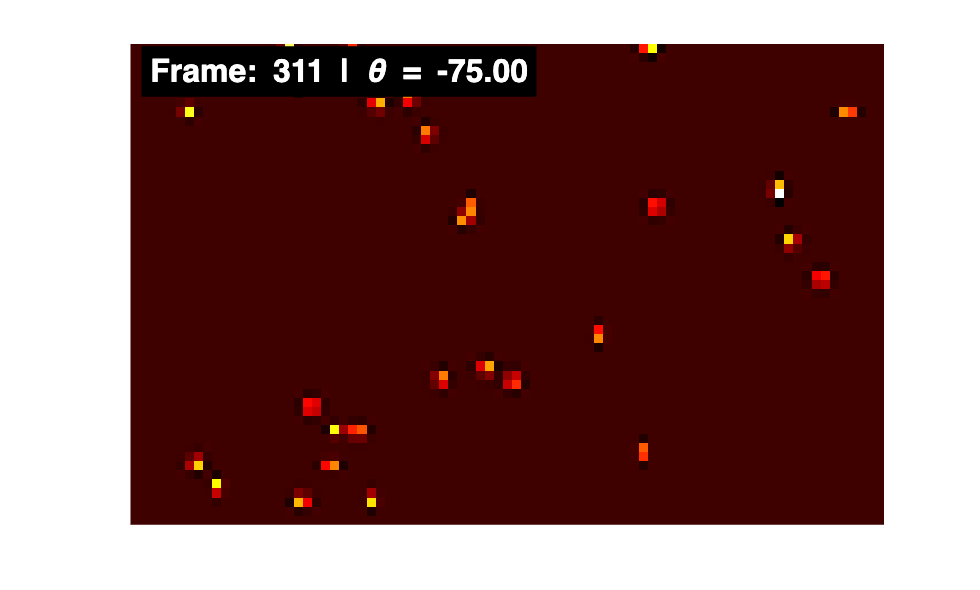

% Test the cropped ROI through the angle scan range
 
vid_image_data = images;
vid_angle_data = angle_data;
fps = 30; frame_skip = 1;
playAngleScanVideoWithOptions2(vid_image_data, vid_angle_data, fps, frame_skip);

clear("vid_image_data","vid_angle_data","fps","frame_skip");

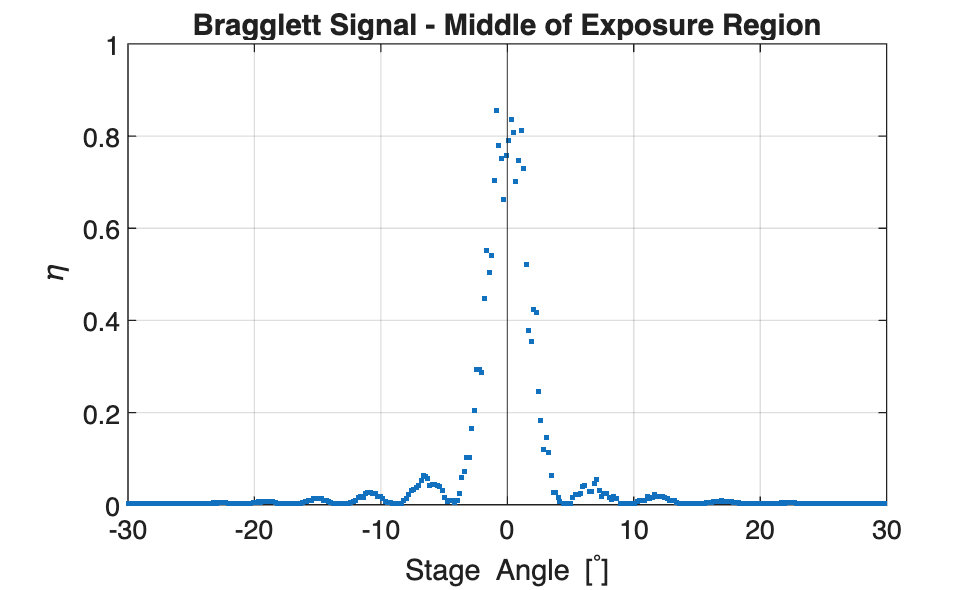

% Choose test points for Braggletts
bragglett_mid_coord  = [43 30]; % Middle of response
% bragglett_side_coord = [7 15]; % Left near boundary of response

% Get DE traces
bragglett_mid_trace = getSignalTrace(bragglett_mid_coord, images);

global_max_counts = 25E03;
DE_maxRef = 0.8;
norm_ref_count = global_max_counts / DE_maxRef;

bragglett_mid_trace = bragglett_mid_trace ./ norm_ref_count;

angle_CWT = angle_data + 45;

% Plot Bragglett signals
figure;
plot(angle_CWT, bragglett_mid_trace, '.'); grid on;
xline(0);
title('Bragglett Signal - Middle of Exposure Region')
xlabel('Stage Angle [^{\circ}]'); ylabel('\eta')

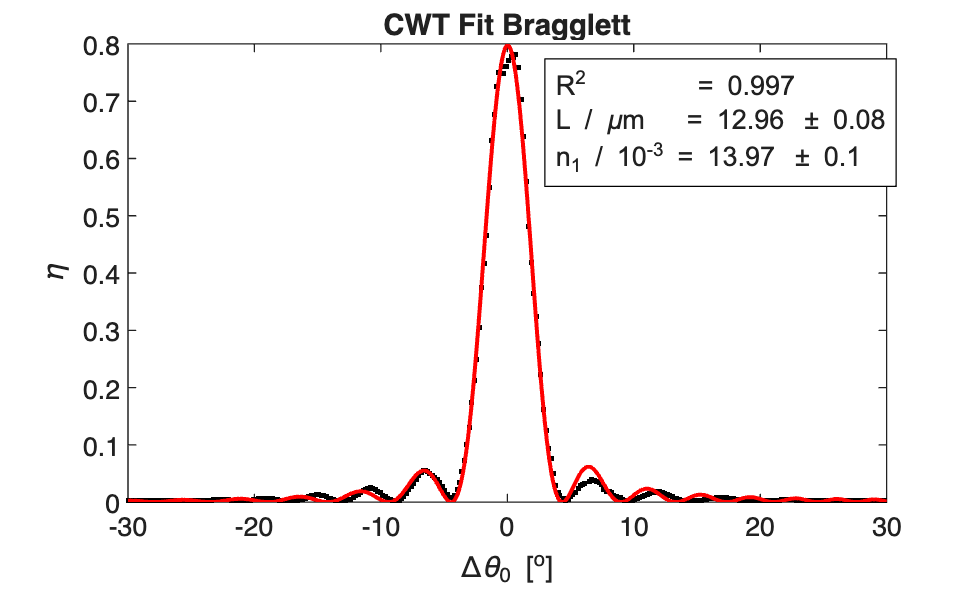


% Fit Bragglett to CWT
smooth_span = 5;
DE_CWT = smooth(bragglett_mid_trace(1,1:1:end),smooth_span)';
plot_title = char('CWT Fit Bragglett');

[~ , ~ , n1, L, GoF] = FitBraggSelectivity(angle_CWT', DE_CWT', ...
    'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
    'RefWrtTheta', -14.46,'ObjWrtTheta', 14.46, ...
    'PlotFit',true, 'PlotResults',true, ...
    'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 532E-09, 'lambdaRed0', 532E-09, ...
    'L0', 14E-6,'n10', 16E-03, ...
    'Born'   , false, ...
    'PlotTitle', plot_title);

## ::::: 2D CWT Fitting :::::

% Make CWT area plots
n1_plot  = NaN([cam_height, cam_width]);
L_plot   = NaN([cam_height, cam_width]);
GoF_plot = NaN([cam_height, cam_width]);

plot_title = char('CWT Fit Bragglett');

% Get DE traces at each pixel
tic;
% poolObj = parpool(12);
for y_pixel = 1:cam_height
    percent_completed = round(((y_pixel / cam_height)*100),2);
    if mod(y_pixel,5) == 0
        fprintf('Progress = %.2f | Time = %.2f\n',percent_completed,toc);
    else
    end
    for x_pixel = 1:cam_width
        % assign pixel coords
        bragglett_pixel_coords = [x_pixel y_pixel];
        
        % Get Bragglett trace
        bragglett_pixel_trace = getSignalTrace(bragglett_pixel_coords, images);
        bragglett_pixel_trace = bragglett_pixel_trace ./ norm_ref_count;
        
        % CWT Fitting
        DE_CWT = smooth(bragglett_pixel_trace(1,1:1:end),smooth_span)';
        
        % Fit Bragg Selectivity of pixel (x,y)
        [~ , ~ , n1, L, GoF] = FitBraggSelectivity(angle_CWT', DE_CWT', ...
            'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
            'RefWrtTheta', -14.46,'ObjWrtTheta', 14.46, ...
            'PlotFit',false, 'PlotResults',false, ...
            'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 532E-09, 'lambdaRed0', 532E-09, ...
            'L0', 14E-6,'n10', 15E-03, ...
            'Born'   , false, ...
            'PlotTitle', plot_title);
        
        % Sort fit parameters into correct coordinates
        n1_plot(y_pixel,x_pixel)  = n1;
        L_plot(y_pixel,x_pixel)   = L;
        GoF_plot(y_pixel,x_pixel) = GoF;
    end
end

Progress = 9.43 | Time = 8.63
Progress = 18.87 | Time = 15.59
Progress = 28.30 | Time = 22.26
Progress = 37.74 | Time = 28.34
Progress = 47.17 | Time = 34.13
Progress = 56.60 | Time = 39.44
Progress = 66.04 | Time = 44.90
Progress = 75.47 | Time = 50.60
Progress = 84.91 | Time = 56.39
Progress = 94.34 | Time = 62.25



% delete(poolObj);
beep;

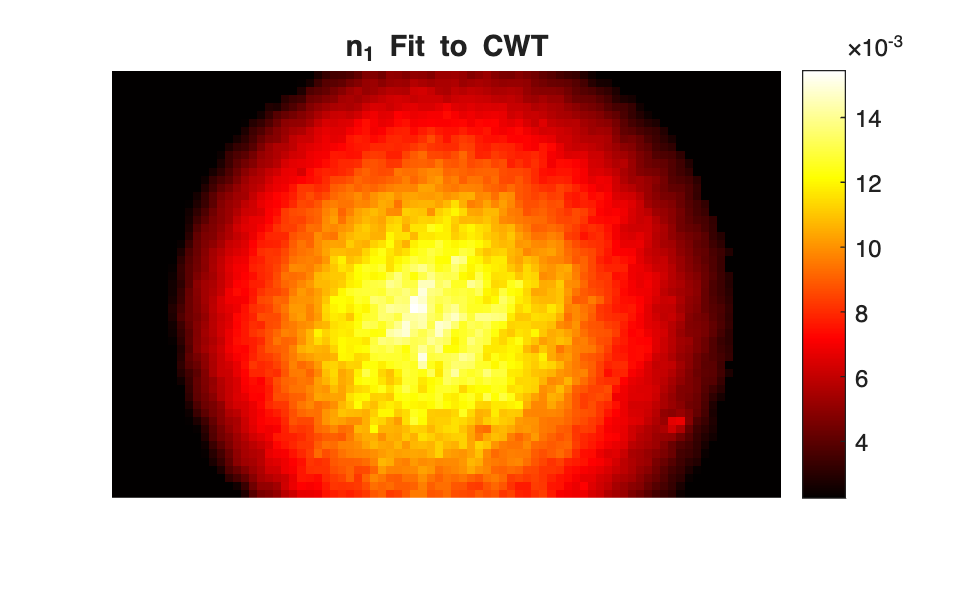

% Logical sorting of good vs bad fit values based on GoF
gof_conditions = GoF_plot > 0.8 & GoF_plot < 1;

% Sort by GoF conditions
n1_sorted  = NaN(size(n1_plot));
L_sorted   = NaN(size(L_plot));
GoF_sorted = NaN(size(GoF_plot));

n1_sorted(gof_conditions) = n1_plot(gof_conditions);
L_sorted(gof_conditions) = L_plot(gof_conditions);
GoF_sorted(gof_conditions) = GoF_plot(gof_conditions);

% plot CWT fit values
figure;
imagesc(n1_sorted); axis image off; colormap("hot")
title('n_1 Fit to CWT'); colorbar;

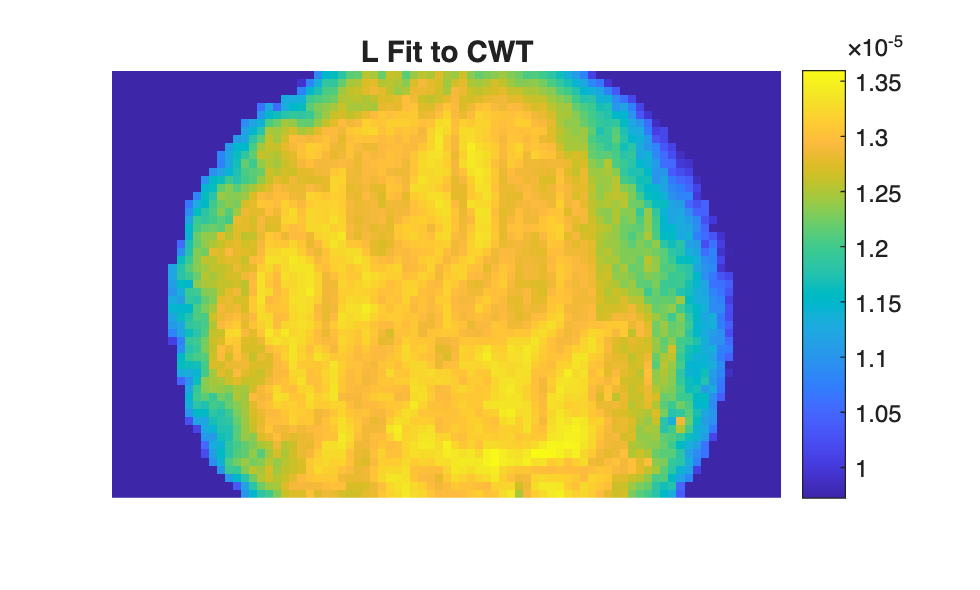


figure;
imagesc(L_sorted); axis image off; 
title('L Fit to CWT'); colorbar;

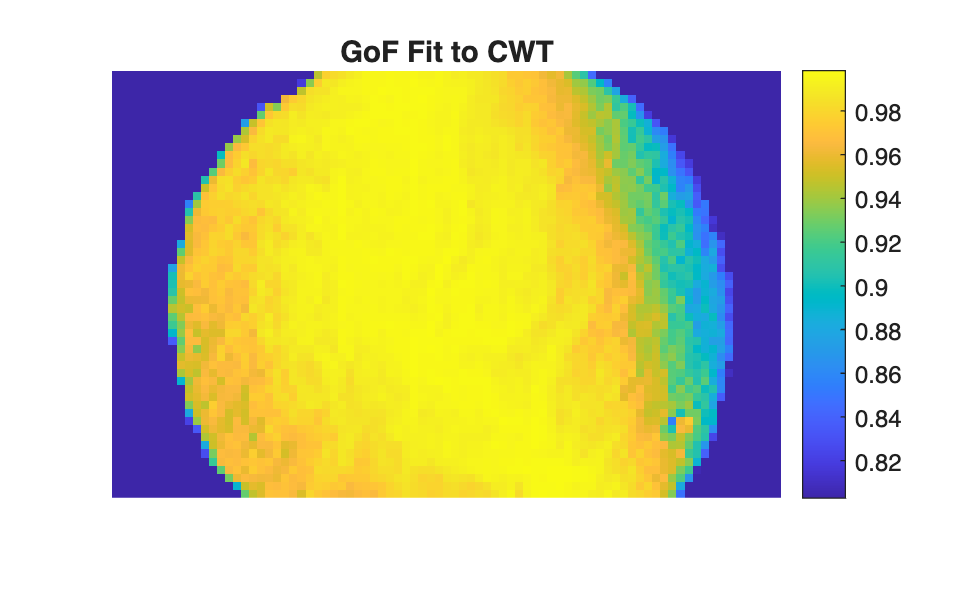


figure;
imagesc(GoF_sorted); axis image off;
title('GoF Fit to CWT'); colorbar;

function signal_trace = getSignalTrace(px_coordinate, image_set)
    % Function to take image pixel coordinates and return the Bragglett
    % trace - more generally, the signal across the frame stack in (x,y)
    x_px = px_coordinate(1);
    y_px = px_coordinate(2);
    signal_trace = image_set(y_px,x_px,:);
    signal_trace = squeeze(signal_trace)';
end

function [matchedVals, matchedIdx] = matchClosestValues(data, testVals, tolerance)
    %MATCHCLOSESTVALUES Finds the closest values in data to each value in testVals
    % within a specified tolerance.
    %
    %   [matchedVals, matchedIdx] = matchClosestValues(data, testVals, tolerance)
    %
    %   Inputs:
    %       data      - Vector of data values
    %       testVals  - Vector of test values to match
    %       tolerance - Maximum allowed distance between testVal and closest data point
    %
    %   Outputs:
    %       matchedVals - Closest values from data (NaN if none within tolerance)
    %       matchedIdx  - Indices of matchedVals in data (NaN if none within tolerance)
    
    data = data(:);
    testVals = testVals(:);
    
    matchedVals = NaN(size(testVals));
    matchedIdx  = NaN(size(testVals));
    
    for i = 1:length(testVals)
        diffs = abs(data - testVals(i));
        [minDiff, idx] = min(diffs);
        if minDiff <= tolerance
            matchedVals(i) = data(idx);
            matchedIdx(i)  = idx;
        end
    end
    % Remove NaNs from data
    matchedVals = matchedVals(~isnan(matchedVals));
    matchedIdx  = matchedIdx(~isnan(matchedIdx));
    
    % Re-orient the vectors
    matchedVals = matchedVals';
    matchedIdx  = matchedIdx';
end

function playAngleScanVideoWithOptions(image_data, angle_data, fps, frame_skip)
    % Function to play the angle scan videos
    
    % Gen data size
    [~, num_frames] = size(image_data);
    
    % Set up figure and axes once
    h_Fig   = figure;
    h_Ax    = axes('Parent', h_Fig);
    h_Img   = imagesc(image_data{1},'Parent', h_Ax); colormap("hot");
    axis image off;
    hold(h_Ax, 'on');                % keep axes active for text overlay
    
    % Text overlay positioned at the upper‑left inside the axes
    h_Label = text(h_Ax, 0.02, 0.98, ...
        sprintf('Frame: 1 | \\theta = %.2f', angle_data(1)), ...
        'Units', 'normalized', ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'top', ...
        'FontWeight', 'bold', ...
        'FontSize', 12, ...
        'Color', 'w', ...
        'Interpreter', 'tex', ...
        'BackgroundColor', 'k', ...
        'Margin', 2);
    
    h_Ax.PositionConstraint = "outerposition";
    
    % Playback loop
    for i_frames = 1:frame_skip:num_frames
        % Update image
        set(h_Img, 'CData', image_data{i_frames});
        
        % Update text overlay
        set(h_Label, 'String', sprintf('Frame: %i | \\theta = %.2f', ...
            i_frames, angle_data(i_frames)));
        
        drawnow;
        pause(1/fps);
    end
end

function playAngleScanVideoWithOptions2(image_data, angle_data, fps, frame_skip)
    % Function to play the angle scan videos DOUBLE FORMAT CWT
    
    % Gen data size
    [~, ~, num_frames] = size(image_data);
    
    % Set up figure and axes once
    h_Fig   = figure;
    h_Ax    = axes('Parent', h_Fig);
    h_Img   = imagesc(image_data(:,:,1),'Parent', h_Ax); colormap("hot");
    axis image off;
    hold(h_Ax, 'on');                % keep axes active for text overlay
    
    % Text overlay positioned at the upper‑left inside the axes
    h_Label = text(h_Ax, 0.02, 0.98, ...
        sprintf('Frame: 1 | \\theta = %.2f', angle_data(1)), ...
        'Units', 'normalized', ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'top', ...
        'FontWeight', 'bold', ...
        'FontSize', 12, ...
        'Color', 'w', ...
        'Interpreter', 'tex', ...
        'BackgroundColor', 'k', ...
        'Margin', 2);
    
    h_Ax.PositionConstraint = "outerposition";
    
    % Playback loop
    for i_frames = 1:frame_skip:num_frames
        % Update image
        set(h_Img, 'CData', image_data(:,:,i_frames));
        
        % Update text overlay
        set(h_Label, 'String', sprintf('Frame: %i | \\theta = %.2f', ...
            i_frames, angle_data(i_frames)));
        
        drawnow;
        pause(1/fps);
    end
end
